initCobraToolbox(false)

E. coli FBA

ecoliPath = [pwd filesep 'model' filesep 'iB21_1397'];
ecoli_core = readCbModel([ecoliPath,'.xml']);

surfNet(ecoli_core_iB21_1397,'fru')

'fru' is not a metabolite, reaction or gene of the model.
Searching for related objects:

  id     Met         metNames, metFormulas, metCharges, matches
 #117        fru[e]  D-Fructose, C6H12O6, 0, metBiGGID:fru, metBioCycID:META:D-Fructopyranose; META:Fructofuranose; META:CPD-15382; META:FRU, metNames:D-Fructose, mets:fru
 #1166       fru[p]  D-Fructose, C6H12O6, 0, metBiGGID:fru, metBioCycID:META:D-Fructopyranose; META:Fructofuranose; META:CPD-15382; META:FRU, metNames:D-Fructose, mets:fru
 #1224       fru[c]  D-Fructose, C6H12O6, 0, metBiGGID:fru, metBioCycID:META:D-Fructopyranose; META:Fructofuranose; META:CPD-15382; META:FRU, metNames:D-Fructose, mets:fru
 #125      fruur[e]  D-F

ecoli_sol = optimizeCbModel(ecoli_core);


Met #365  sucr[e], Sucrose C12H22O11, C12H22O11, metCharges: 0

Consuming reactions:
  #390  EX_sucr_e, Bd: 0 / 1000, Sucrose exchange, grRules: 
sucr[e]   -> 
  #2328  SUCRtex, Bd: -1000 / 1000, Sucrose transport transport via diffusion (extracellular to periplasm), grRules: ( B21_00241 or B21_00940 or B21_01360 or ompC )
sucr[e]   <=>   

model_ec = ecoli_core_iB21_1397;
model_ec = addReaction(model_ec,'EX_fru_e','lowerBound',-10); % no straight glucose

% model_ec = addReaction(model_ec,'EX_sucr_e','lowerBound',-300);
% model_ec = changeObjective(model_ec,{'BIOMASS_Ec_iJO1366_core_53p95M'},1000);
% model_ec = addReaction(model_ec,'SUCRe', ...
%     'reactionName','Sucrose hydrolyzing enxyme extracellular', ...
%     'metaboliteList',{'h2o[e]','sucr[e]','fru[e]','glc__D[e]'}, ...
%     'stoichCoeffList',[-1,-1,1,1], ...
%     'lowerBound',0, ...
%     'subSystem','S-Alternate_Carbon_Metabolism');
% surfNet(model_ec,'SUCRe')
ecoli_sol2 = optimizeCbModel(model_ec);
printFluxVector(model_ec,ecoli_sol2.x,true,true) % only prints nonzero rows

DM_4crsol_c                   	   0.0001032
DM_5drib_c                    	   0.0001042
DM_amob_c                     	   9.259e-07
DM_mththf_c                   	   0.0002074
BIOMASS_Ec_iJO1366_core_53p95M	      0.4629
EX_ca2_e                      	    -0.00241
EX_fe2_e                      	   -0.007435
EX_cit_e                      	       8.784
EX_cl_e                       	    -0.00241
EX_co2_e                      	       2.704
EX_cobalt2_e                  	  -1.157e-05
EX_cu2_e                      	  -0.0003282
EX_fru_e                      	         -10
EX_dha_e                      	       2.113
EX_glc__D_e                   	        -3.5
EX_k_e                        	    -0.09036
EX_glyc3p_e                   	     0.08318
EX_glyclt_e                   	   0.0003097
EX_h_e                        	       30.61
EX_h2o_e                      	        32.5
EX_meoh_e                     	   9.259e-07
EX_mg2_e                      	   -0.004016
EX_mn2_e                      	 

ecoli_sol2 = optimizeCbModel(model_ec);

ans = 391

Step number	Biomass
Dynamic FBA analysis in progress ...
100%    [........................................]


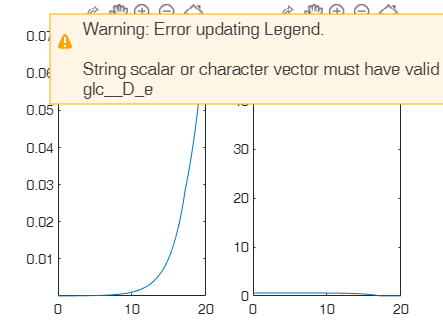

% Ecoli_BL21_fom1 = changeObjective(Ecoli_BL21_fom,{'FDH','BIOMASS_Ec_iJO1366_core_53p95M'},2);
% Ecoli_BL21_fom
smc = [55.45,0.6]; % Glucose, Acetate concentration (all in mM)

Xec = 1e-5; % initial biomass
dt = 1.0/10.0; % time steps
time = 20.0/dt; % simulation time

plot_rxn = {'EX_glc__D_e','EX_fald_e'};

[concentrationMatrix, excRxnNames, timeVec,...
    biomassVec] = dynamicFBA(Ecoli_BL21_fom, plot_rxn, smc, Xec, dt, time, plot_rxn);

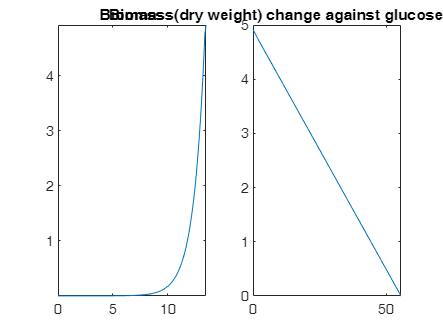

plot(biomassVec(:),concentrationMatrix(20,:))

ecoli_core_iB21_1397 = addReaction(ecoli_core_iB21_1397,'EX_nh4_e','lowerBound',-5);

ecoli_core_iB21_1397 = addReaction(ecoli_core_iB21_1397,'EX_glc__D_e','lowerBound',-3.5);

ecoli_sol2 = optimizeCbModel(ecoli_core_iB21_1397);
printFluxVector(ecoli_core_iB21_1397,ecoli_sol2.x,true,true) % only prints nonzero rows

DM_4crsol_c                   	    7.43e-05
DM_5drib_c                    	   7.497e-05
DM_amob_c                     	   6.664e-07
DM_mththf_c                   	   0.0001493
BIOMASS_Ec_iJO1366_core_53p95M	      0.3332
EX_ca2_e                      	   -0.001734
EX_fe2_e                      	   -0.005352
EX_cl_e                       	   -0.001734
EX_co2_e                      	       7.322
EX_cobalt2_e                  	   -8.33e-06
EX_cu2_e                      	  -0.0002362
EX_glc__D_e                   	        -3.5
EX_k_e                        	    -0.06504
EX_h_e                        	       3.062
EX_h2o_e                      	       16.12
EX_meoh_e                     	   6.664e-07
EX_mg2_e                      	   -0.002891
EX_mn2_e                      	  -0.0002302
EX_mobd_e                     	  -4.298e-05
EX_nh4_e                      	      -3.599
EX_ni2_e                      	  -0.0001076
EX_o2_e                       	      -6.611
EX_pi_e                       	 

% model_ec_HCHO = addReaction(model_ec_HCHO,'EX_sucr_e','lowerBound',0);
%model_ec_HCHO = addReaction(model_ec_HCHO,)

%model_ec_HCHO = addReaction(model_ec_HCHO,'')

Robustness analysis in progress ...
100%    [........................................]


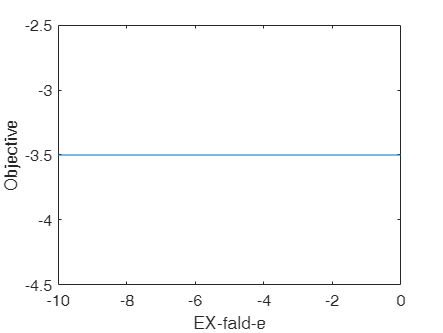

%ecoli_core_iB21_1397
%ecoli_core_iEC1356_Bl21DE3
%ecoli_core_iECD_1397
npoints = 100;
[controlFlux, objFlux] = robustnessAnalysis(Ecoli_BL21_fom, ...
    {'EX_glc__D_e'},npoints,true,{'EX_fald_e'},'min');


close all;
biomass_flux = []


biomass_flux =

     []



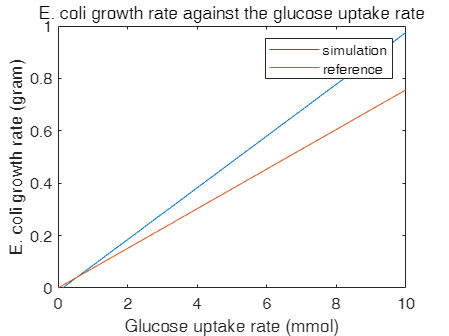

ex_flux = [];

%[controlFlux, objFlux] = robustnessAnalysis(model,...
%'EX_na1_e',225,true,'SPP','max');
% glc = 0.42*180.138*0.001

y = linspace(10,0,npoints);
x = 0.42*180.138*0.001*y;
biomass_flux(1:npoints,1) = objFlux;
% type(2:101,1) = "sim";
biomass_flux(1:npoints,2) = x;
% type(102:201,1) = "exp";
ex_flux(1:npoints,1) =  -controlFlux;
ex_flux(1:npoints,2) =  y;
% ex_flux(2:101,2) = "sim";
% ex_flux(102:201,2) = "exp";
plot_flux.biomass = biomass_flux;
plot_flux.ex = ex_flux;
low = 1;
up = 200;
x = plot_flux.biomass(low:up,:);
y = plot_flux.ex(low:up,:);
figure
plot(y,x);
legend('simulation','reference')
title('E. coli growth rate against the glucose uptake rate')
xlabel('Glucose uptake rate (mmol)') 
ylabel('E. coli growth rate (gram)')


plot_flux.type = type;
% g = gramm('x',plot_flux.biomass,'y', plot_flux.ex,'group',plot_flux.type);
% g.geom_line();
% g.draw();
% outpath = [pwd filesep 'output'];
% g.export('file_name','wtf','export_path',outpath,'file_type','png');


%surfNet(Ecoli_BL21_fom,"FDH");
surfNet(ecoli_core,"sucr[e]", 0,ecoli_sol2.x,1,1);


Met #365  sucr[e], Sucrose C12H22O11, C12H22O11, metCharges: 0

Consuming reactions with non-zero fluxes :
  #2742  SUCRe (537.3055), Bd: 0 / 1000, Sucrose hydrolyzing enxyme extracellular, grRules: 
h2o[e] + sucr[e]   ->   fru[e] + glc__D[e] 
Producing reactions with non-zero fluxes :
  #390  EX_sucr_e (-537.3055), Bd: -1000 / 1000, Sucrose exchange, grRules: 
sucr[e]   <- 



ecoli_sol2 = optimizeCbModel(ecoli_core_iB21_1397);
printFluxVector(ecoli_core_iB21_1397,ecoli_sol2.x,true,true) % only prints nonzero rows

DM_4crsol_c                   	   8.052e-05
DM_5drib_c                    	   8.124e-05
DM_amob_c                     	   7.222e-07
DM_mththf_c                   	   0.0001618
BIOMASS_Ec_iJO1366_core_53p95M	      0.3611
EX_ca2_e                      	   -0.001879
EX_fe2_e                      	   -0.005799
EX_cit_e                      	      0.2773
EX_cl_e                       	   -0.001879
EX_co2_e                      	       7.514
EX_cobalt2_e                  	  -9.027e-06
EX_cu2_e                      	   -0.000256
EX_glc__D_e                   	          -4
EX_k_e                        	    -0.07048
EX_glyclt_e                   	   0.0002416
EX_h_e                        	        4.15
EX_h2o_e                      	        17.6
EX_meoh_e                     	   7.222e-07
EX_mg2_e                      	   -0.003132
EX_mn2_e                      	  -0.0002495
EX_mobd_e                     	  -4.658e-05
EX_nh4_e                      	        -3.9
EX_ni2_e                      	 